clear;
clc;

% 建立DH模型
th(1) = 0; d(1) = 8.55; a(1) = 0; alp(1) = pi/2;
th(2) = 0; d(2) = 0; a(2) = 10.5;alp(2) = 0;
th(3) = 0; d(3) = 0; a(3) = 9.8; alp(3) = 0;
th(4) = 0; d(4) = 0; a(4) = 0; alp(4) = 0;
th(5) = pi/2; d(5) = 0; a(5) = 0; alp(5) = pi/2;
th(6) = 0; d(6) = 14.7; a(6) = 0; alp(6) = 0;
% DH参数 theta d a alp
L1 = Link([th(1), d(1), a(1), alp(1), 0]);
L2 = Link([th(2), d(2), a(2), alp(2), 0]);
L3 = Link([th(3), d(3), a(3), alp(3), 0]);
L4 = Link([th(4), d(4), a(4), alp(4), 0]);
L5 = Link([th(5), d(5), a(5), alp(5), 0]); 
L6 = Link([th(6), d(6), a(6), alp(6), 0], jointtype='P');
L1.qlim = [45*pi/180, 135*pi/180];
L2.qlim = [45*pi/180, 135*pi/180];
L3.qlim = [-45*pi/180, 45*pi/180];
L4.qlim = [45*pi/180, 135*pi/180];
L5.qlim = [-45*pi/180, 45*pi/180];
L6.qlim = [45*pi/180, 135*pi/180]; % hand
robot = SerialLink([L1, L2, L3, L4, L5, L6]); 
robot.name='robotic arm';
robot.display()

 
robot = 
 
robotic arm:: 6 axis, RRRRRR, stdDH, slowRNE                     
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|       8.55|          0|     1.5708|          0|
|  2|         q2|          0|       10.5|          0|          0|
|  3|         q3|          0|        9.8|          0|          0|
|  4|         q4|          0|          0|          0|          0|
|  5|         q5|          0|          0|     1.5708|          0|
|  6|         q6|       14.7|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


% 逆运动学解算
theta = sym('theta', [1, 6]);
% syms d1 d2 d3 d4 d5 d6
% syms a1 a2 a3 a4 a5 a6
% syms alpha1 alpha2 alpha3 alpha4 alpha5 alpha6
T0_1 = DH_transform(theta(1), d(1), alp(1), a(1));
T1_2 = DH_transform(theta(2), d(2), alp(2), a(2));
T2_3 = DH_transform(theta(3), d(3), alp(3), a(3));
T3_4 = DH_transform(theta(4), d(4), alp(4), a(4));
T4_5 = DH_transform(theta(5), d(5), alp(5), a(5));
T5_6 = DH_transform(theta(6), d(6), alp(6), a(6)); % hand
T0_6 = T0_1*T1_2*T2_3*T3_4*T4_5*T5_6;
Theta=ones(1,6);
Theta(1) = Theta(1) * 180;
Theta(2) = Theta(2) * 31+90;
Theta(3) = Theta(3) * 78;
Theta(4) = Theta(4) * 21;
Theta(5) = Theta(5) * 90+90;
Theta(6) = Theta(6) * 0; % hand
Theta

Theta =    180   121    78    21   180     0


Theta = Theta/180*pi;
T = robot.fkine(Theta)

 

T = 
   -0.7660         0   -0.6428     5.225
         0         1         0         0
    0.6428         0   -0.7660     3.099
         0         0         0         1


% T = [-0.866,0,-0.5,-27.62;
%      0,1,0,0;
%      0.5,0,-0.866,5.58;
%      0,0,0,1];
targetAngle = round(robot.ikine(T)*180/pi, 1)

targetAngle =          0  -14.9000    7.0000  -38.3000  -38.3000         0


% 运动控制
startAngle = [0, 0, 0, 0, 0, 0];
targetAngle(1) = limit(targetAngle(1));
targetAngle(2) = limit(targetAngle(2)-90)+90;
targetAngle(3) = limit(targetAngle(3));
targetAngle(4) = limit(targetAngle(4));
targetAngle(5) = limit(targetAngle(5)-90)+90;
targetAngle(6) = limit(targetAngle(6));
x=10;
y=27.62;
z=5.58;
[angle1, angle2, angle3, angle4] = InverseKinematics(d(1), a(2), a(3), d(6), -x, -y, z)

angle1 = -109.9031

angle2 = 23.9305

angle3 = 84.4126

angle4 = 27.1031

targetAngle = [angle1, angle2+90, angle3, angle4, 90, 0];
targetAngle

targetAngle =  -109.9031  113.9305   84.4126   27.1031   90.0000         0


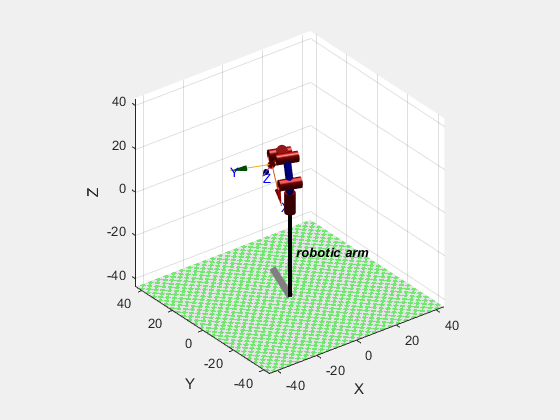

figure('Visible','on');
while ~isequal(startAngle, targetAngle)
    startAngle(1) = LinearInterpolation(startAngle(1), targetAngle(1), 9);
    startAngle(2) = LinearInterpolation(startAngle(2), targetAngle(2), 6);
    startAngle(3) = LinearInterpolation(startAngle(3), targetAngle(3), 3);
    startAngle(4) = LinearInterpolation(startAngle(4), targetAngle(4), 3);
    startAngle(5) = LinearInterpolation(startAngle(5), targetAngle(5), 9);
    startAngle(6) = LinearInterpolation(startAngle(6), targetAngle(6), 9);
    angle = [startAngle(1), startAngle(2), startAngle(3), startAngle(4), startAngle(5), startAngle(6)];
    theta = angle*pi/180;
    robot.plot(theta);
    hold on;
end
hold off;